addpath("/home/james/Documents/leuven/year-2/SVM/LSSVMlab")
addpath("/home/james/Documents/leuven/year-2/SVM/svm_toolbox_1/svm")

load iris.mat

degree_i = [1,2,3,4,5,6,7,8,9,10];
accs = zeros(10);

for i = degree_i
    type='classification'; 
    gam = 1; % gamma
    t = 1; % intercept
    degree = i;

    [alpha, b] = trainlssvm({Xtrain, Ytrain, type, gam, [t; degree], 'poly_kernel'});

    figure;
    plotlssvm({Xtrain, Ytrain, type, gam, [t; degree], 'poly_kernel', 'preprocess'}, {alpha,b});
    title (sprintf('Polynomial kernel with %d degree', degree))
    [Yht, Zt] = simlssvm({Xtrain, Ytrain, type, gam, [t; degree], 'poly_kernel'}, {alpha,b}, Xtest);
    err = sum(Yht~=Ytest);
    acc = 1 - err/length(Ytest);
    accs(i) = acc;
    fprintf('\n on test: #misclass = %d, error rate = %.2f%%\n', err, err/length(Ytest)*100)
end

sigmas = logspace(-3, 3, 100);
accs_sigma = zeros(100);

for i = 1:length(sigmas)
    model_type = 'classification';
    gamma = 1; % gamma
    t = 1; % intercept
    sigma = sigmas(i);

    [alpha, b] = trainlssvm({Xtrain, Ytrain, model_type, gamma, sigma, 'RBF_kernel'});

%     figure;
%     plotlssvm({Xtrain, Ytrain, model_type, gamma, sigma, 'RBF_kernel', 'preprocess'}, {alpha,b});
%     title (sprintf('RBF kernel sig2 =  %d', sigma))
    [Yht, Zt] = simlssvm({Xtrain, Ytrain, model_type, gamma, sigma, 'RBF_kernel'}, {alpha,b}, Xtest);
    err = sum(Yht~=Ytest);
    acc = 1 - err/length(Ytest);
    accs_sigma(i) = acc;
    fprintf('\n on test: #misclass = %d, error rate = %.2f%%\n', err, err/length(Ytest)*100)
end

figure;
semilogx(sigmas, accs_sigma)
ylabel("Accuracy")
xlabel("sigma")
ylim([0,1.1])
xlim([0.001, 1000])

gammas = logspace(-3, 5, 100);
accs_gamma = zeros(100);

for i = 1:length(sigmas)
    model_type = 'classification';
    sigma = 5; % gamma
    t = 1; % intercept
    gamma = gammas(i);

    [alpha, b] = trainlssvm({Xtrain, Ytrain, model_type, gamma, sigma, 'RBF_kernel'});

%     figure;
%     plotlssvm({Xtrain, Ytrain, model_type, gamma, sigma, 'RBF_kernel', 'preprocess'}, {alpha,b});
%     title (sprintf('RBF kernel sig2 =  %d', sigma))
    [Yht, Zt] = simlssvm({Xtrain, Ytrain, model_type, gamma, sigma, 'RBF_kernel'}, {alpha,b}, Xtest);
    err = sum(Yht~=Ytest);
    acc = 1 - err/length(Ytest);
    accs_gamma(i) = acc;
    fprintf('\n on test: #misclass = %d, error rate = %.2f%%\n', err, err/length(Ytest)*100)
end

figure;
semilogx(gammas, accs_gamma)
ylabel("Accuracy")
xlabel("gamma")
ylim([0,1.1])
xlim([0.001, 100000])

sigma_values = logspace(-3,3,100); 
gamma_values = logspace(-3,3,100);

rand_split_mse = zeros(100, 100);
cv_split_mse = zeros(100, 100);
loo_split_mse = zeros(100, 100);

for i = 1:length(sigma_values)
    for j = 1:length(gamma_values)
        rand_split_mse(i,j)= rsplitvalidate({Xtrain, Ytrain, 'c', gamma_values(j), sigma_values(i), 'RBF_kernel'}, 0.80 , 'misclass');
        cs_split_mse(i,j) = crossvalidate({Xtrain, Ytrain, 'c', gamma_values(j), sigma_values(i), 'RBF_kernel'}, 10 , 'misclass');
        loo_split_mse(i,j) = leaveoneout({Xtrain, Ytrain, 'c', gamma_values(j), sigma_values(i), 'RBF_kernel'}, 'misclass');
    end 
end

bottom = min([rand_split_mse(:); cs_split_mse(:); loo_split_mse(:)])
top = max([rand_split_mse(:); cs_split_mse(:); loo_split_mse(:)])

set(gcf, 'position', [0,0, 1800, 400])
subplot(1,3,1)
imagesc(sigma_values, gamma_values, rand_split_mse)
axis('xy')
xlabel("gamma")
ylabel("sigma")
caxis manual
caxis([bottom top]);
title('Random Split') 

subplot(1,3,2)
imagesc(sigma_values, gamma_values, cs_split_mse)
axis('xy')
xlabel("gamma")
ylabel("sigma")
caxis manual
caxis([bottom top]);
title('Cross Validation') 

subplot(1,3,3)
imagesc(sigma_values, gamma_values, loo_split_mse)
axis('xy')
xlabel("gamma")
ylabel("sigma")
caxis manual
caxis([bottom top]);
title('LOOCV') 

colorbar

[gam_s, sig2_s, cost_s] = tunelssvm({Xtrain, Ytrain, 'c', [], [], 'RBF_kernel'}, 'simplex', 'crossvalidatelssvm', {10,'misclass'});
[gam_g, sig2_g, cost_g] = tunelssvm({Xtrain, Ytrain, 'c', [], [], 'RBF_kernel'}, 'gridsearch', 'crossvalidatelssvm', {10,'misclass'});
[gam_s, sig2_s, cost_s]
[gam_g, sig2_g, cost_g]

[alpha, b] = trainlssvm({Xtrain, Ytrain, 'c', gam_s, sig2_s, 'RBF_kernel'});
[Yest, Ylatent] = simlssvm({Xtrain, Ytrain, 'c', gam_s, sig2_s, 'RBF_kernel'}, {alpha, b}, Xtest);
roc(Ylatent,Ytest)

[alpha, b] = trainlssvm({Xtrain, Ytrain, 'c', gam_s, sig2_s , 'RBF_kernel'});
[Yest, Ylatent] = simlssvm({Xtrain, Ytrain, 'c', gam_s, sig2_s , 'RBF_kernel'}, {alpha, b}, Xtrain);
roc(Ylatent,Ytrain)

[alpha, b] = trainlssvm({Xtrain, Ytrain, 'c', gam_g, sig2_g,'RBF_kernel'});
[Yest, Ylatent] = simlssvm({Xtrain, Ytrain, 'c', gam_g, sig2_g,'RBF_kernel'}, {alpha, b}, Xtest);
roc(Ylatent,Ytest)

[alpha, b] = trainlssvm({Xtrain, Ytrain, 'c', gam_g, sig2_g, 'RBF_kernel'});
[Yest, Ylatent] = simlssvm({Xtrain, Ytrain, 'c', gam_g, sig2_g, 'RBF_kernel'}, {alpha, b}, Xtrain);
roc(Ylatent,Ytrain)

bay_modoutClass({Xtrain, Ytrain, 'c', gam_s, sig2_s}, 'figure');
colorbar

bay_modoutClass({Xtrain, Ytrain, 'c', .1, 0.01}, 'figure'); 
bay_modoutClass({Xtrain, Ytrain, 'c', .1, 0.1}, 'figure');
bay_modoutClass({Xtrain, Ytrain, 'c', .1, 1}, 'figure');
bay_modoutClass({Xtrain, Ytrain, 'c', .1, 10}, 'figure'); 

bay_modoutClass({Xtrain, Ytrain, 'c', 1, 0.01}, 'figure'); 
bay_modoutClass({Xtrain, Ytrain, 'c', 1, 0.1}, 'figure');
bay_modoutClass({Xtrain, Ytrain, 'c', 1, 1}, 'figure');
bay_modoutClass({Xtrain, Ytrain, 'c', 1, 10}, 'figure'); 

bay_modoutClass({Xtrain, Ytrain, 'c', 10, 0.01}, 'figure'); 
bay_modoutClass({Xtrain, Ytrain, 'c', 10, 0.1}, 'figure');
bay_modoutClass({Xtrain, Ytrain, 'c', 10, 1}, 'figure');
bay_modoutClass({Xtrain, Ytrain, 'c', 10, 10}, 'figure'); 

bay_modoutClass({Xtrain, Ytrain, 'c', 100, 0.01}, 'figure'); 
bay_modoutClass({Xtrain, Ytrain, 'c', 100, 0.1}, 'figure');
bay_modoutClass({Xtrain, Ytrain, 'c', 100, 1}, 'figure');
bay_modoutClass({Xtrain, Ytrain, 'c', 100, 10}, 'figure');

bay_modoutClass({Xtrain, Ytrain, 'c', 0.01, 0.1}, 'figure'); 
bay_modoutClass({Xtrain, Ytrain, 'c', 0.1, 0.1}, 'figure'); 
bay_modoutClass({Xtrain, Ytrain, 'c', 1, 0.1}, 'figure');
bay_modoutClass({Xtrain, Ytrain, 'c', 10, 0.1}, 'figure');
bay_modoutClass({Xtrain, Ytrain, 'c', 100, 0.1}, 'figure');

load ripley.mat
figure;
hold on;

x_train1=vertcat(Xtrain(:,1), Xtest(:,1))
x_train2=vertcat(Xtrain(:,2), Xtest(:,2))
y_data=vertcat(Ytrain,Ytest)

gscatter(x_train1,x_train2,y_data,'rb','xo');
title('Ripley Dataset')
xlabel('X1');
ylabel('X2');

type='classification';
[gam_s, sig2_s, cost_s] = tunelssvm({Xtrain, Ytrain, 'c', [], [], 'RBF_kernel'}, 'simplex', 'crossvalidatelssvm', {10,'misclass'});

kernel = 'lin_kernel'
lfold = 10
model = {Xtrain, Ytrain,'c', [], [], kernel, 'csa'}
[gam, sig2, cost] = tunelssvm(model, 'simplex', 'crossvalidatelssvm', {lfold, 'misclass'})
[alpha, b] = trainlssvm({Xtrain, Ytrain,'c', gam, sig2, kernel})
plotlssvm({Xtrain, Ytrain, 'c', gam, sig2, kernel, 'preprocess'}, {alpha, b})

[Ysim,Ylatent]=simlssvm({Xtrain,Ytrain,'c',gam,sig2,kernel},{alpha,b},Xtest)
roc(Ylatent,Ytest)

kernel='poly_kernel'
lfold=10
model={Xtrain,Ytrain,'c',[],[],kernel,'csa'}
[gam,sig2,cost]=tunelssvm(model,'simplex','crossvalidatelssvm',{lfold,'misclass'})
[alpha,b]=trainlssvm({Xtrain,Ytrain,'c',gam,sig2,kernel})
plotlssvm({Xtrain,Ytrain,'c',gam,sig2,kernel,'preprocess'},{alpha,b})

[Ysim,Ylatent]=simlssvm({Xtrain,Ytrain,'c',gam,sig2,kernel},{alpha,b},Xtest)
roc(Ylatent,Ytest)

kernel='RBF_kernel'
lfold=10
model={Xtrain,Ytrain,'c',[],[],kernel,'csa'}
[gam,sig2,cost]=tunelssvm(model,'simplex','crossvalidatelssvm',{lfold,'misclass'})
[alpha,b]=trainlssvm({Xtrain,Ytrain,'c',gam,sig2,kernel})
plotlssvm({Xtrain,Ytrain,'c',gam,sig2,kernel,'preprocess'},{alpha,b})

[Ysim,Ylatent]=simlssvm({Xtrain,Ytrain,'c',gam,sig2,kernel},{alpha,b},Xtest)
roc(Ylatent,Ytest)

clear
load breast.mat

data = vertcat(trainset, testset)

data = 	1.0e+03 *

    0.0194    0.0235    0.1291    1.1550    0.0001    0.0002    0.0002    0.0001    0.0002    0.0001    0.0005    0.0018    0.0040    0.0604    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0216    0.0305    0.1449    1.4170    0.0001    0.0003    0.0003    0.0002    0.0003    0.0001
    0.0140    0.0213    0.0898    0.6034    0.0001    0.0001    0.0000    0.0000    0.0002    0.0001    0.0003    0.0015    0.0017    0.0221    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0153    0.0303    0.0983    0.7155    0.0001    0.0002    0.0001    0.0001    0.0002    0.0001
    0.0123    0.0149    0.0783    0.4691    0.0001    0.0000    0.0000    0.0000    0.0002    0.0001    0.0004    0.0009    0.0026    0.0301    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0132    0.0169    0.0841    0.5331    0.0001    0.0001    0.0000    0.0000    0.0002    0.0001
    0.0180    0.0169    0.1175    0.9900    0.0001    0.0001    0.0001    0.00

label = vertcat(labels_train, labels_test)

label =      1
    -1
    -1
     1
    -1
    -1
    -1
    -1
     1
    -1



norm_data = normalize(data)

norm_data =     1.4962    0.9789    1.5281    1.4211    0.4508    0.9744    1.4564    1.0293    0.6069   -0.3962    0.4296    1.0607    0.5791    0.4413    1.1887    0.3932    0.2404    0.6149    0.1594    0.0582    1.1133    0.7895    1.1201    0.9421    0.6102    0.2703    0.3528    0.6358    0.0311   -0.4322
   -0.0276    0.4558   -0.0897   -0.1463   -0.4025   -0.6607   -0.9305   -0.7721   -1.0747   -0.6299   -0.5275    0.5187   -0.5930   -0.4016    0.1159   -0.6504   -0.8147   -0.2846   -0.9572   -0.3288   -0.1943    0.7489   -0.2676   -0.2899   -0.1607   -0.6544   -1.0060   -0.5321   -1.0906   -0.4305
   -0.5072   -1.0090   -0.5629   -0.5279   -0.6783   -1.1102   -0.8493   -0.7314   -0.8777   -0.8098   -0.0789   -0.5602   -0.1306   -0.2239    0.2202   -0.9486   -0.6236   -0.2425    1.1078   -0.8930   -0.6392   -1.4362   -0.6890   -0.6103   -1.2074   -1.1874   -1.0688   -1.0144   -0.9743   -1.3402
    1.1075   -0.5672    1.0507    0.9523   -0.4899    0.3571    0.2534    0.3510   -0

[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED] = pca(norm_data)

COEFF =     0.2189   -0.2339   -0.0085   -0.0414   -0.0378    0.0187   -0.1241   -0.0075   -0.2231    0.0955    0.0415   -0.0511   -0.0120    0.0595   -0.0511    0.1506    0.2029    0.1467   -0.2254   -0.0497    0.0686   -0.0729    0.0986    0.1826    0.0192    0.1295   -0.1315   -0.2112   -0.2115    0.7024
    0.1037   -0.0597    0.0645    0.6031    0.0495   -0.0322    0.0114    0.1307    0.1127    0.2409   -0.3022   -0.2549   -0.2035   -0.0216   -0.1079    0.1578   -0.0387   -0.0411   -0.0298   -0.2441   -0.4484   -0.0948    0.0006   -0.0988   -0.0847    0.0246   -0.0174    0.0001    0.0105    0.0003
    0.2275   -0.2152   -0.0093   -0.0420   -0.0374    0.0173   -0.1145   -0.0187   -0.2237    0.0864    0.0168   -0.0389   -0.0441    0.0485   -0.0399    0.1145    0.1948    0.1583   -0.2396   -0.0177    0.0698   -0.0752    0.0402    0.1166   -0.0270    0.1253   -0.1154   -0.0843   -0.3838   -0.6899
    0.2210   -0.2311    0.0287   -0.0534   -0.0103   -0.0019   -0.0517    0.0347   -0.195

SCORE =     3.7922   -1.0253    0.8978    0.7598    0.7572   -0.5223   -1.3873    0.0966   -0.8556    0.4300    0.3017    0.3197   -0.5364   -0.0136    0.1148   -0.0737    0.1243    0.1603   -0.4182    0.0566   -0.0949    0.0124   -0.2406   -0.0452   -0.0096    0.3005    0.2356   -0.0465    0.0162    0.0010
   -2.3322   -1.3478    0.2325    1.2118   -0.0515   -1.2356   -0.1741   -0.1341   -0.3585    0.2936   -0.1015    0.0700    0.4673    0.1501    0.0654    0.1122    0.2003    0.1590   -0.1213    0.2150    0.0702    0.0573    0.0227    0.0620   -0.0389    0.0850    0.0534    0.0047   -0.0066    0.0042
   -3.6441   -1.2403    1.3854   -1.6125    0.1728    0.5965   -0.2936    0.4072   -0.0434   -0.6090   -0.6101   -0.2406   -0.1987   -0.3284   -0.2166    0.2617   -0.2456   -0.0828    0.0770    0.1057    0.0736    0.1017    0.0093    0.0114    0.1158    0.0346   -0.0299   -0.0134   -0.0158    0.0040
    0.9809   -2.2085   -1.6984   -0.9701   -1.1822    0.1435   -0.4567   -0.0678   -0.449

LATENT =    13.2816
    5.6914
    2.8179
    1.9806
    1.6487
    1.2074
    0.6752
    0.4766
    0.4169
    0.3507


TSQUARED =    37.6728
    9.7494
   12.7119
   21.1437
   12.9868
   13.0183
   22.6357
   32.4991
   62.8383
  107.1123


EXPLAINED =    44.2720
   18.9712
    9.3932
    6.6021
    5.4958
    4.0245
    2.2507
    1.5887
    1.3896
    1.1690


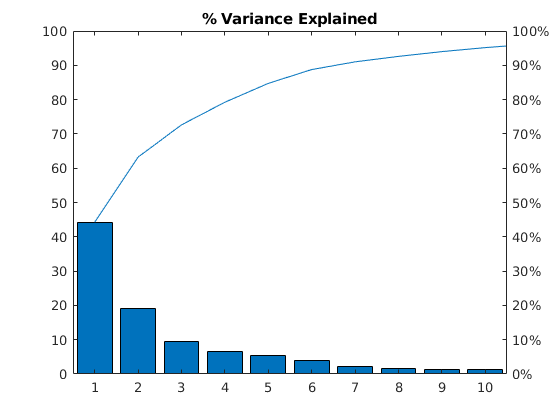


figure();
pareto(EXPLAINED)
title("% Variance Explained")


class1 = find(label==-1)

class1 =      2
     3
     5
     6
     7
     8
    10
    11
    12
    14


class2 = find(label==1)

class2 =      1
     4
     9
    13
    15
    19
    21
    22
    26
    27


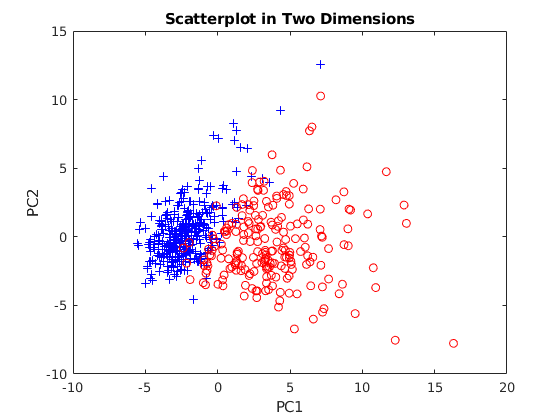


scores_class1 = SCORE(class1,:);
scores_class2 = SCORE(class2,:);

figure;
plot(scores_class1(:,1),scores_class1(:,2),'b+',scores_class2(:,1),scores_class2(:,2),'ro')
title('Scatterplot in Two Dimensions')
xlabel('PC1');
ylabel('PC2');

kernel = 'lin_kernel'
kfold = 10
model = {trainset, labels_train, 'c', [], [], kernel, 'csa'}
[gam, sig2, cost] = tunelssvm(model,'simplex','crossvalidatelssvm', {kfold, 'misclass'})
[alpha, b] = trainlssvm({trainset, labels_train, 'c', gam, sig2, kernel})
plotlssvm({trainset, labels_train, 'c', gam, sig2, kernel, 'preprocess'}, {alpha, b})

[Ysim, Ylatent] = simlssvm({trainset, labels_train, 'c', gam, sig2, kernel}, {alpha, b}, testset)
roc(Ylatent, labels_test)
hold on;


kernel='poly_kernel'
kfold=10
model={trainset,labels_train,'c',[],[],kernel,'csa'}
[gam,sig2,cost]=tunelssvm(model,'simplex','crossvalidatelssvm',{kfold,'misclass'})
[alpha,b]=trainlssvm({trainset,labels_train,'c',gam,sig2,kernel})
plotlssvm({trainset,labels_train,'c',gam,sig2,kernel,'preprocess'},{alpha,b})

[Ysim,Ylatent]=simlssvm({trainset,labels_train,'c',gam,sig2,kernel},{alpha,b},testset)
roc(Ylatent,labels_test)
hold on;

kernel='RBF_kernel'
kfold=10
model={trainset,labels_train,'c',[],[],kernel,'csa'}
[gam,sig2,cost]=tunelssvm(model,'simplex','crossvalidatelssvm',{kfold,'misclass'})
[alpha,b]=trainlssvm({trainset,labels_train,'c',gam,sig2,kernel})
plotlssvm({trainset,labels_train,'c',gam,sig2,kernel,'preprocess'},{alpha,b})

[Ysim,Ylatent]=simlssvm({trainset,labels_train,'c',gam,sig2,kernel},{alpha,b},testset)
roc(Ylatent,labels_test)
hold on;

clear
load diabetes.mat

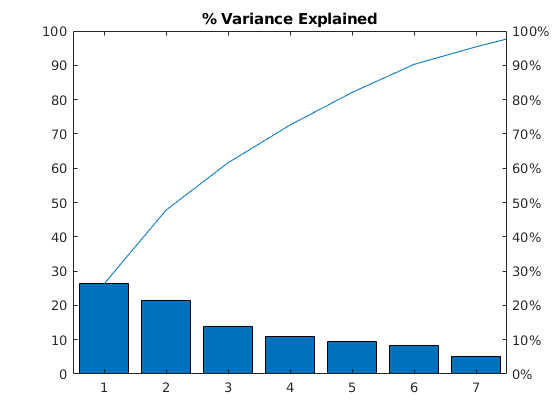

data=vertcat(trainset, testset);
label=vertcat(labels_train,labels_test);

norm_data = normalize(data);
[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED] = pca(norm_data);

figure();
pareto(EXPLAINED)
title("% Variance Explained")


class1 = find(label==-1)

class1 =      1
     2
     3
     4
     5
    11
    12
    13
    15
    17


class2 = find(label==1)

class2 =      6
     7
     8
     9
    10
    14
    16
    18
    22
    24


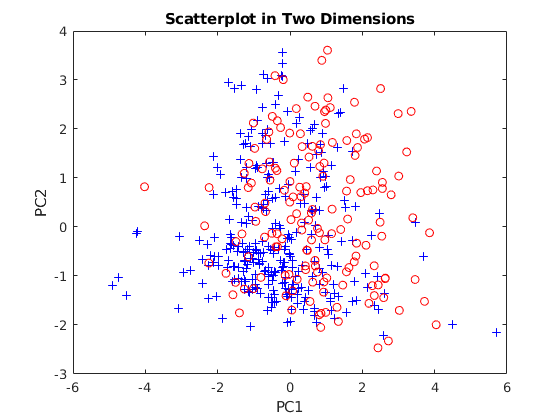


scores_class1 = SCORE(class1,:);
scores_class2 = SCORE(class2,:);

figure;
plot(scores_class1(:,1),scores_class1(:,2),'b+',scores_class2(:,1),scores_class2(:,2),'ro')
title('Scatterplot in Two Dimensions')
xlabel('PC1');
ylabel('PC2');

kernel = 'lin_kernel' %0.2433

kernel = 'lin_kernel'

kfold = 10

kfold = 10

model = {trainset, labels_train, 'c', [], [], kernel, 'csa'}

model = 1×7 cell array
    {300×8 double}    {300×1 double}    {'c'}    {0×0 double}    {0×0 double}    {'lin_kernel'}    {'csa'}


[gam, sig2, cost] = tunelssvm(model,'simplex','crossvalidatelssvm', {kfold, 'misclass'})


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         0.26828
                                          F(X)=         0.24333
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 lin_kernel
 

 3. starting value:                   0.26828

 Iteration   Func-count    min f(x)    log(gamma)      Procedure

     1           2     2.433333e-01     -1.3157           initial 
     2           5     2.433333e-01     -1.3157           shrink 
     3           7     2.433333e-01     -1.3157           contract outside 
     4          10     2.433333e-01     -1.3157           shrink 
     5          13     2.433333e-01     -1.3157           shrink 
     6          16     2.433333e-01     -1.

gam = 0.2683


sig2 =

     []



cost = 0.2433

[alpha, b] = trainlssvm({trainset, labels_train, 'c', gam, sig2, kernel})

alpha =    -0.2825
   -0.0593
   -0.2787
   -0.2809
   -0.1111
    0.2091
    0.1740
    0.2244
    0.0265
    0.4286


b = -0.5560

Start Plotting...

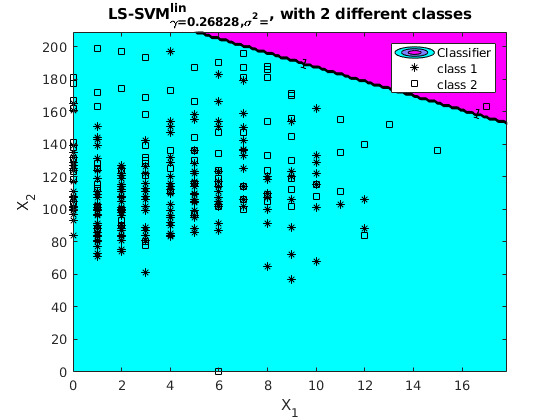

finished


ans = struct with fields:
           type: 'c'
          x_dim: 8
          y_dim: 1
        nb_data: 300
    kernel_type: 'lin_kernel'
     preprocess: 'preprocess'
      prestatus: 'ok'
         xtrain: [300×8 double]
         ytrain: [300×1 double]
       selector: [1×300 double]
            gam: 0.2683
    kernel_pars: []
       x_delays: 0
       y_delays: 0
          steps: 1
         latent: 'no'
           code: 'original'
       codetype: 'none'
    pre_xscheme: 'accccccc'
    pre_yscheme: 'b'
      pre_xmean: [0 118.9100 67.9433 20.2467 76.7300 31.9017 0.4779 34.0267]
       pre_xstd: [0 29.7279 20.1172 16.3860 122.2800 7.8495 0.3212 11.9620]
      pre_ymean: -1
       pre_ystd: 1
         status: 'trained'
        weights: []
          alpha: [300×1 double]
              b: -0.5560


plotlssvm({trainset, labels_train, 'c', gam, sig2, kernel, 'preprocess'}, {alpha, b})


[Ysim, Ylatent] = simlssvm({trainset, labels_train, 'c', gam, sig2, kernel}, {alpha, b}, testset)

Ysim =     -1
    -1
    -1
    -1
    -1
    -1
     1
     1
    -1
     1


Ylatent =    -0.5271
   -0.0651
   -0.3246
   -0.5330
   -0.3396
   -0.0526
    0.0129
    0.3368
   -0.3610
    0.0295


roc(Ylatent, labels_test)

ans = 0.8433

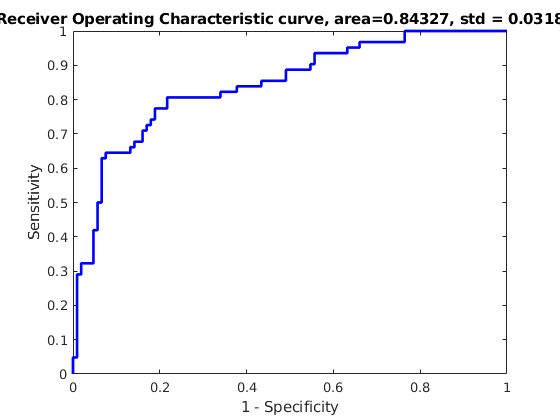

hold on;


kernel = 'poly_kernel' %0.2833

kernel = 'poly_kernel'

kfold = 10

kfold = 10

model = {trainset, labels_train, 'c', [], [], kernel, 'csa'}

model = 1×7 cell array
    {300×8 double}    {300×1 double}    {'c'}    {0×0 double}    {0×0 double}    {'poly_kernel'}    {'csa'}


[gam, sig2, cost] = tunelssvm(model,'simplex','crossvalidatelssvm', {kfold, 'misclass'})


   Determine initial hyperparameters for simplex...
  |-                                              -|
  **************************************************

 1. Simulated Annealing results:          [gam]         0.006858
                                          [t]           1.7566
                                          [degree]      3
                                          F(X)=         0.33667
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 poly_kernel
 

 3. starting values:                   0.006858      1.7566           3

 Iteration   Func-count    min f(x)    log(gamma)      log(t)        Procedure

     1           3     3.366667e-01     -4.9823         0.5634         initial   
     2           4     3.366667e-01     -4.9823         0.5634         reflect   
     3           6     3.200000e-01     -5.5823         -1.2366         expand   
    

gam = 1.8739e-04

sig2 =     0.5291    3.0000


cost = 0.2833

[alpha, b] = trainlssvm({trainset, labels_train, 'c', gam, sig2, kernel})

alpha = 	1.0e+-3 *

   -0.1936
    0.0010
   -0.2211
   -0.1547
   -0.0869
    0.0116
    0.2223
    0.1905
    0.0485
    0.2559


b = -0.5184

Start Plotting...

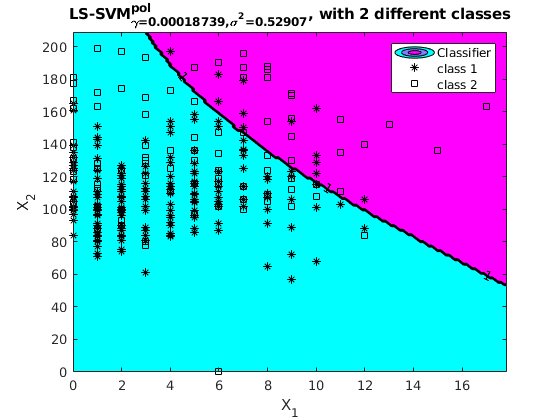

finished


ans = struct with fields:
           type: 'c'
          x_dim: 8
          y_dim: 1
        nb_data: 300
    kernel_type: 'poly_kernel'
     preprocess: 'preprocess'
      prestatus: 'ok'
         xtrain: [300×8 double]
         ytrain: [300×1 double]
       selector: [1×300 double]
            gam: 1.8739e-04
    kernel_pars: [0.5291 3]
       x_delays: 0
       y_delays: 0
          steps: 1
         latent: 'no'
           code: 'original'
       codetype: 'none'
    pre_xscheme: 'accccccc'
    pre_yscheme: 'b'
      pre_xmean: [0 118.9100 67.9433 20.2467 76.7300 31.9017 0.4779 34.0267]
       pre_xstd: [0 29.7279 20.1172 16.3860 122.2800 7.8495 0.3212 11.9620]
      pre_ymean: -1
       pre_ystd: 1
         status: 'trained'
        weights: []
          alpha: [300×1 double]
              b: -0.5184


plotlssvm({trainset, labels_train, 'c', gam, sig2, kernel, 'preprocess'}, {alpha, b})


[Ysim, Ylatent] = simlssvm({trainset, labels_train, 'c', gam, sig2, kernel}, {alpha, b}, testset)

Ysim =     -1
    -1
    -1
    -1
     1
    -1
    -1
     1
    -1
    -1


Ylatent =    -0.6073
   -0.3447
   -0.4895
   -0.5774
    0.0250
   -0.2126
   -0.0925
    0.0350
   -0.3792
   -0.3266


roc(Ylatent, labels_test)

ans = 0.7991

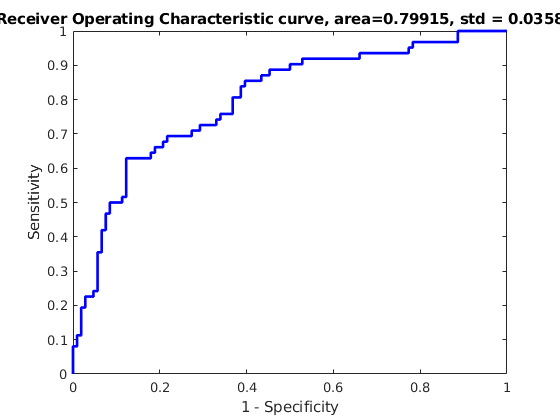

hold on;


kernel = 'RBF_kernel' %0.266

kernel = 'RBF_kernel'

kfold = 10

kfold = 10

model = {trainset, labels_train, 'c', [], [], kernel, 'csa'}

model = 1×7 cell array
    {300×8 double}    {300×1 double}    {'c'}    {0×0 double}    {0×0 double}    {'RBF_kernel'}    {'csa'}


[gam, sig2, cost] = tunelssvm(model,'simplex','crossvalidatelssvm', {kfold, 'misclass'})


   Determine initial tuning parameters for simplex...: # cooling cycle(s) 1
  |-                                              -|
  ************************************************** done

 1. Coupled Simulated Annealing results:  [gam]         28.6083
                                          [sig2]        6608.0879
                                          F(X)=         0.26
 
 TUNELSSVM: chosen specifications:
 2. optimization routine:           simplex
    cost function:                  crossvalidatelssvm
    kernel function                 RBF_kernel
 

 3. starting values:                   28.608313      6608.0879

 Iteration   Func-count    min f(x)    log(gamma)    log(sig2)    Procedure

     1           3     2.600000e-01     3.3537        9.9960      initial 
     2           5     2.600000e-01     3.3537        9.9960      contract outside 
optimisation terminated sucessfully (TolFun criterion)

Simplex results: 
X=28.608313   21939.624467, F(X)=2.600000e-01 

Obtained hy

gam = 28.6083

sig2 = 2.1940e+04

cost = 0.2600

[alpha, b] = trainlssvm({trainset, labels_train, 'c', gam, sig2, kernel})

alpha =   -25.9024
  -16.6160
  -22.4725
  -16.5736
  -14.2979
   26.7575
   35.4547
   31.6075
   30.1164
   40.7377


b = 0.0721

Start Plotting...

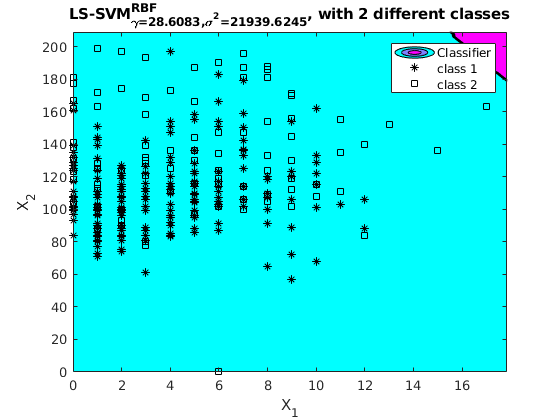

finished


ans = struct with fields:
           type: 'c'
          x_dim: 8
          y_dim: 1
        nb_data: 300
    kernel_type: 'RBF_kernel'
     preprocess: 'preprocess'
      prestatus: 'ok'
         xtrain: [300×8 double]
         ytrain: [300×1 double]
       selector: [1×300 double]
            gam: 28.6083
    kernel_pars: 2.1940e+04
       x_delays: 0
       y_delays: 0
          steps: 1
         latent: 'no'
           code: 'original'
       codetype: 'none'
    pre_xscheme: 'accccccc'
    pre_yscheme: 'b'
      pre_xmean: [0 118.9100 67.9433 20.2467 76.7300 31.9017 0.4779 34.0267]
       pre_xstd: [0 29.7279 20.1172 16.3860 122.2800 7.8495 0.3212 11.9620]
      pre_ymean: -1
       pre_ystd: 1
         status: 'trained'
        weights: []
          alpha: [300×1 double]
              b: 0.0721


plotlssvm({trainset, labels_train, 'c', gam, sig2, kernel, 'preprocess'}, {alpha, b})


[Ysim, Ylatent] = simlssvm({trainset, labels_train, 'c', gam, sig2, kernel}, {alpha, b}, testset)

Ysim =     -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1
    -1


Ylatent =    -0.3802
   -0.3808
   -0.4335
   -0.4766
   -0.1106
   -0.3096
   -0.2231
   -0.0165
   -0.4008
   -0.3302


roc(Ylatent, labels_test)

ans = 0.8180

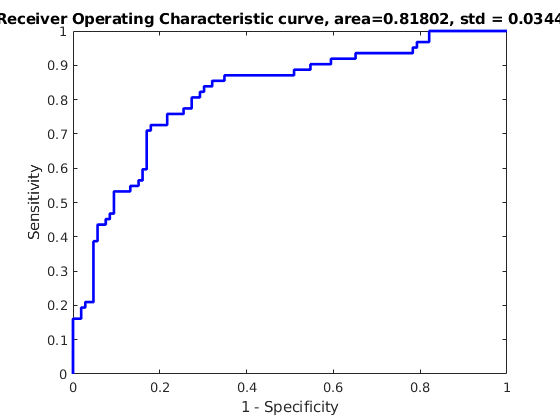

hold on;